# Precision Functional Mapping Figures for Sun et al., 2026

Michael Sun, Ph.D.

## Housekeeping

Note that the analysis requires the use of CANLabCore Tools to be downloaded in a Matlab working directory.

% Check if CanlabCore Tools are installed
toolboxName = 'CANLab Core'; % Replace with the actual toolbox name
functionName = 'fmri_data'; % Replace with a function or file name from the toolbox

% Check if the function or file associated with the toolbox exists
if exist(functionName, 'file') == 2
    fprintf('%s is installed.\n', toolboxName);
else
    fprintf('%s is not installed.\n', toolboxName);
end

## Load Data

load('PrecisionSVM_Results_Workspace.mat')

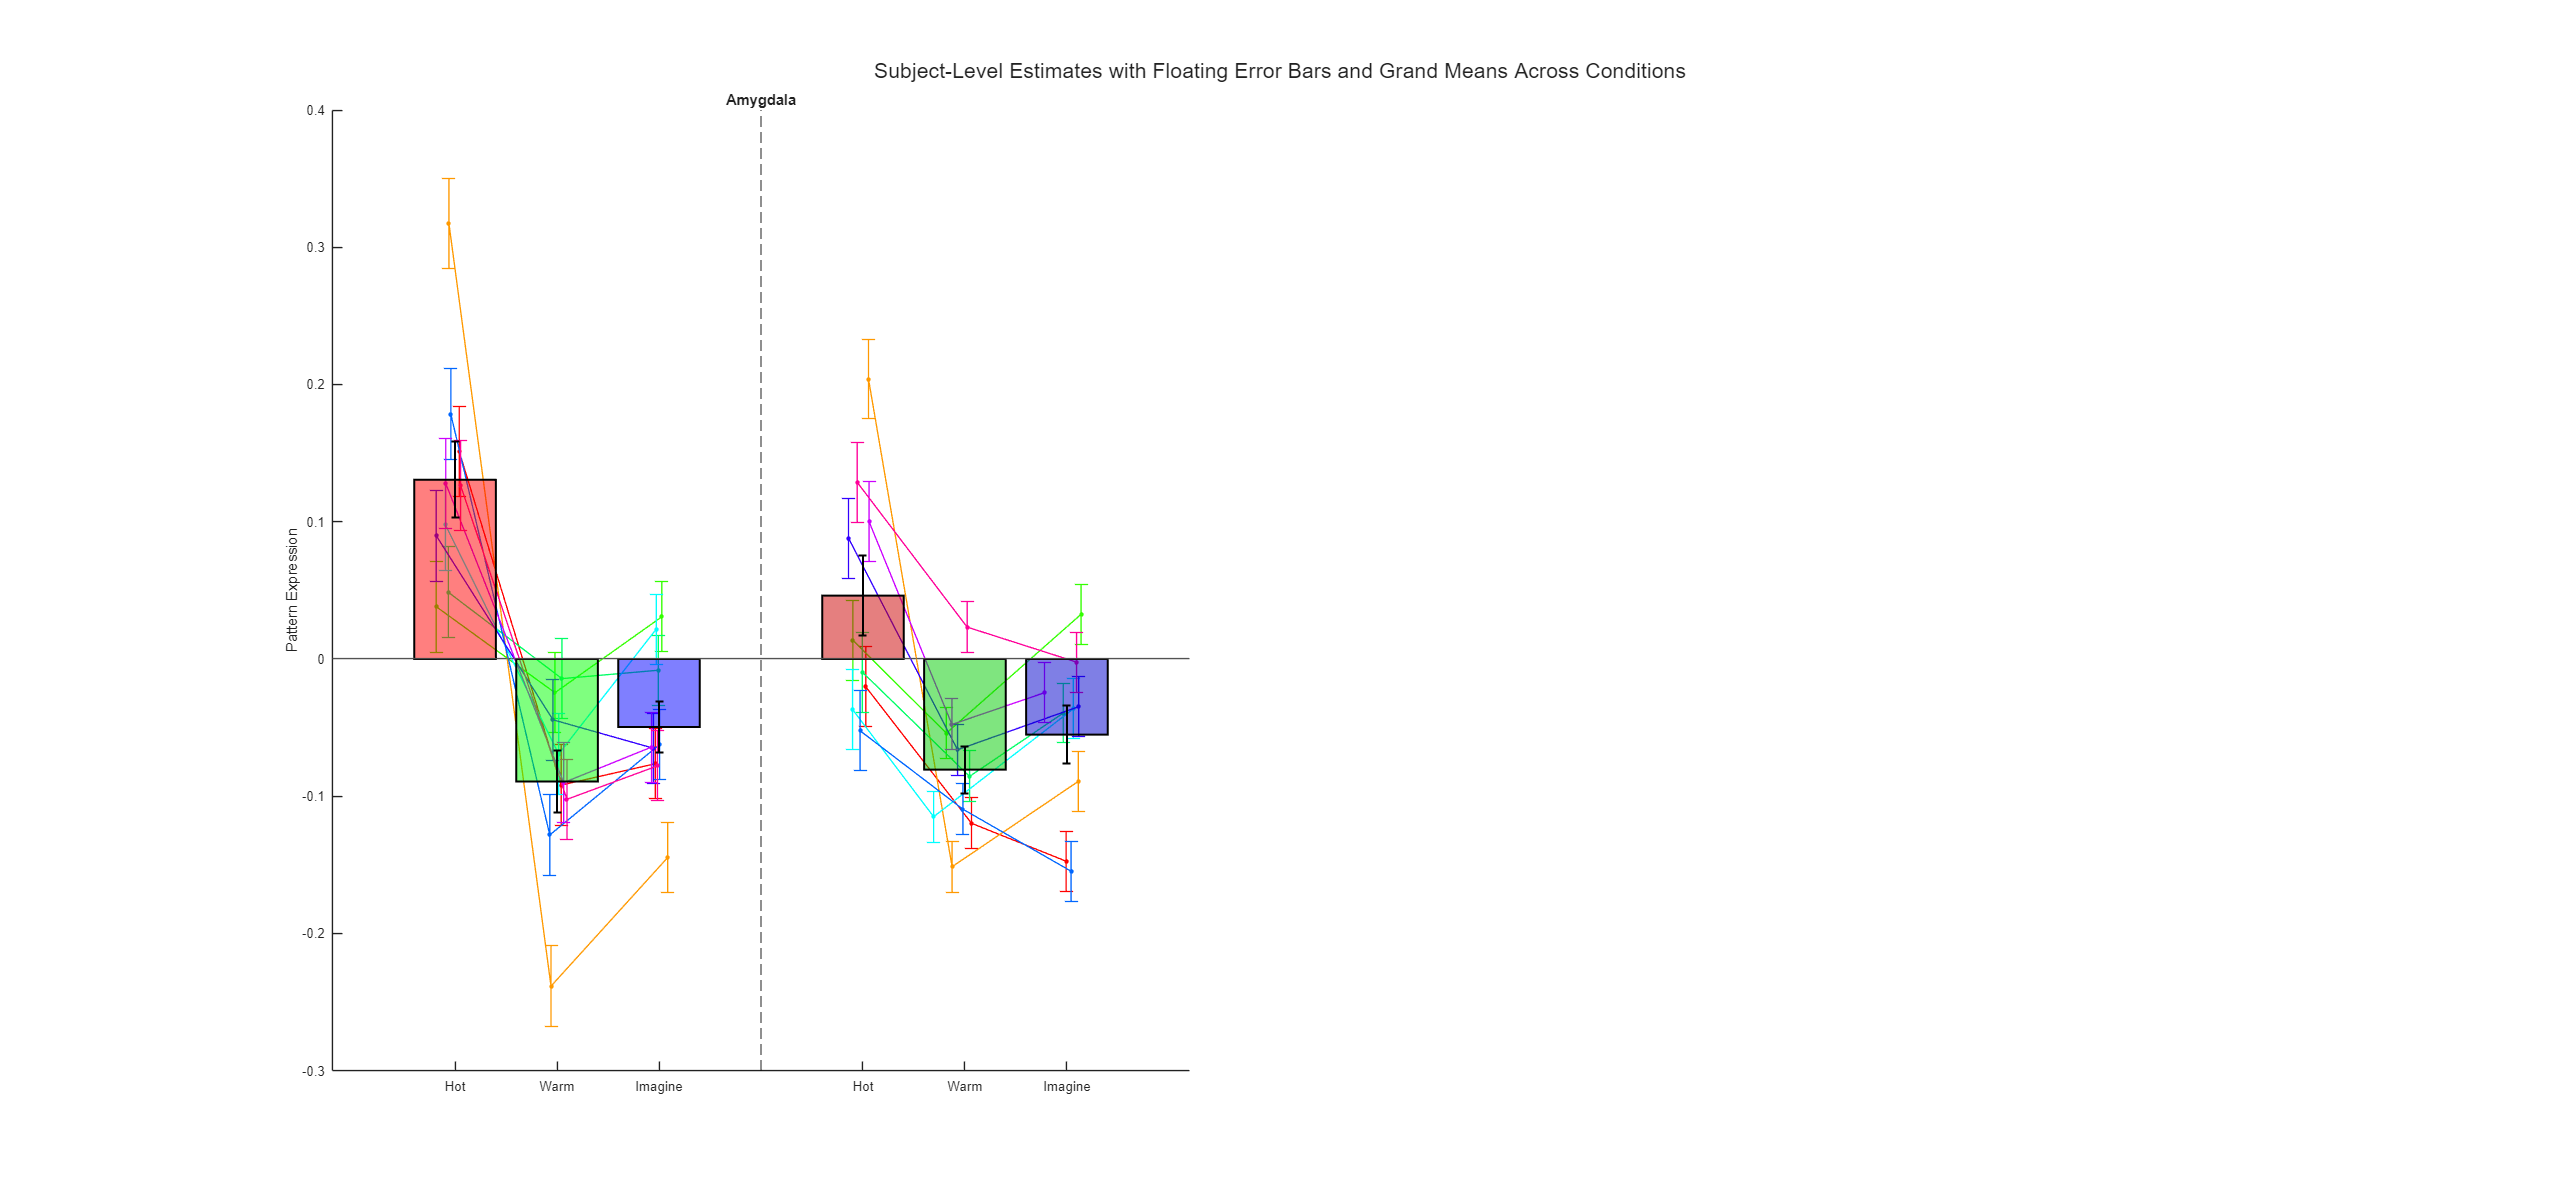

svgdir = fullfile(pwd, 'figures_svg');
if ~exist(svgdir,'dir'), mkdir(svgdir); end

## Figure 1: Bar Plot

Subject-level data can be overlayed upon barplots like in the bar-plots of Figure 5. The left three plots for each ROI shows the Hot-Warm individualized pattern-classifier for Hot, Warm, and Imagine images for matching body-sites between image and classifier. The right shows Hot, Warm, and Imagine pattern expression for non-matching body-sites between image and classifier. 

unique_rois = {'Amygdala'};

labels = 1×14 cell array
    {'Amygdala'}    {'Periqacqueductal Gray'}    {'Parabrachial Nuclei'}    {'S2'}    {'Thalamus (IL)'}    {'Thalamus (MD)'}    {'Thalamus (VPLM)'}    {'Anterior Insula'}    {'Anterior Midcingulate/Medial Prefrontal Cortex'}    {'Dorsoposterior Insula'}    {'Hypothalamus'}    {'Middle Insula'}    {'Rostral Ventral Medulla'}    {'S1'}


Compressed NIfTI files are not supported.


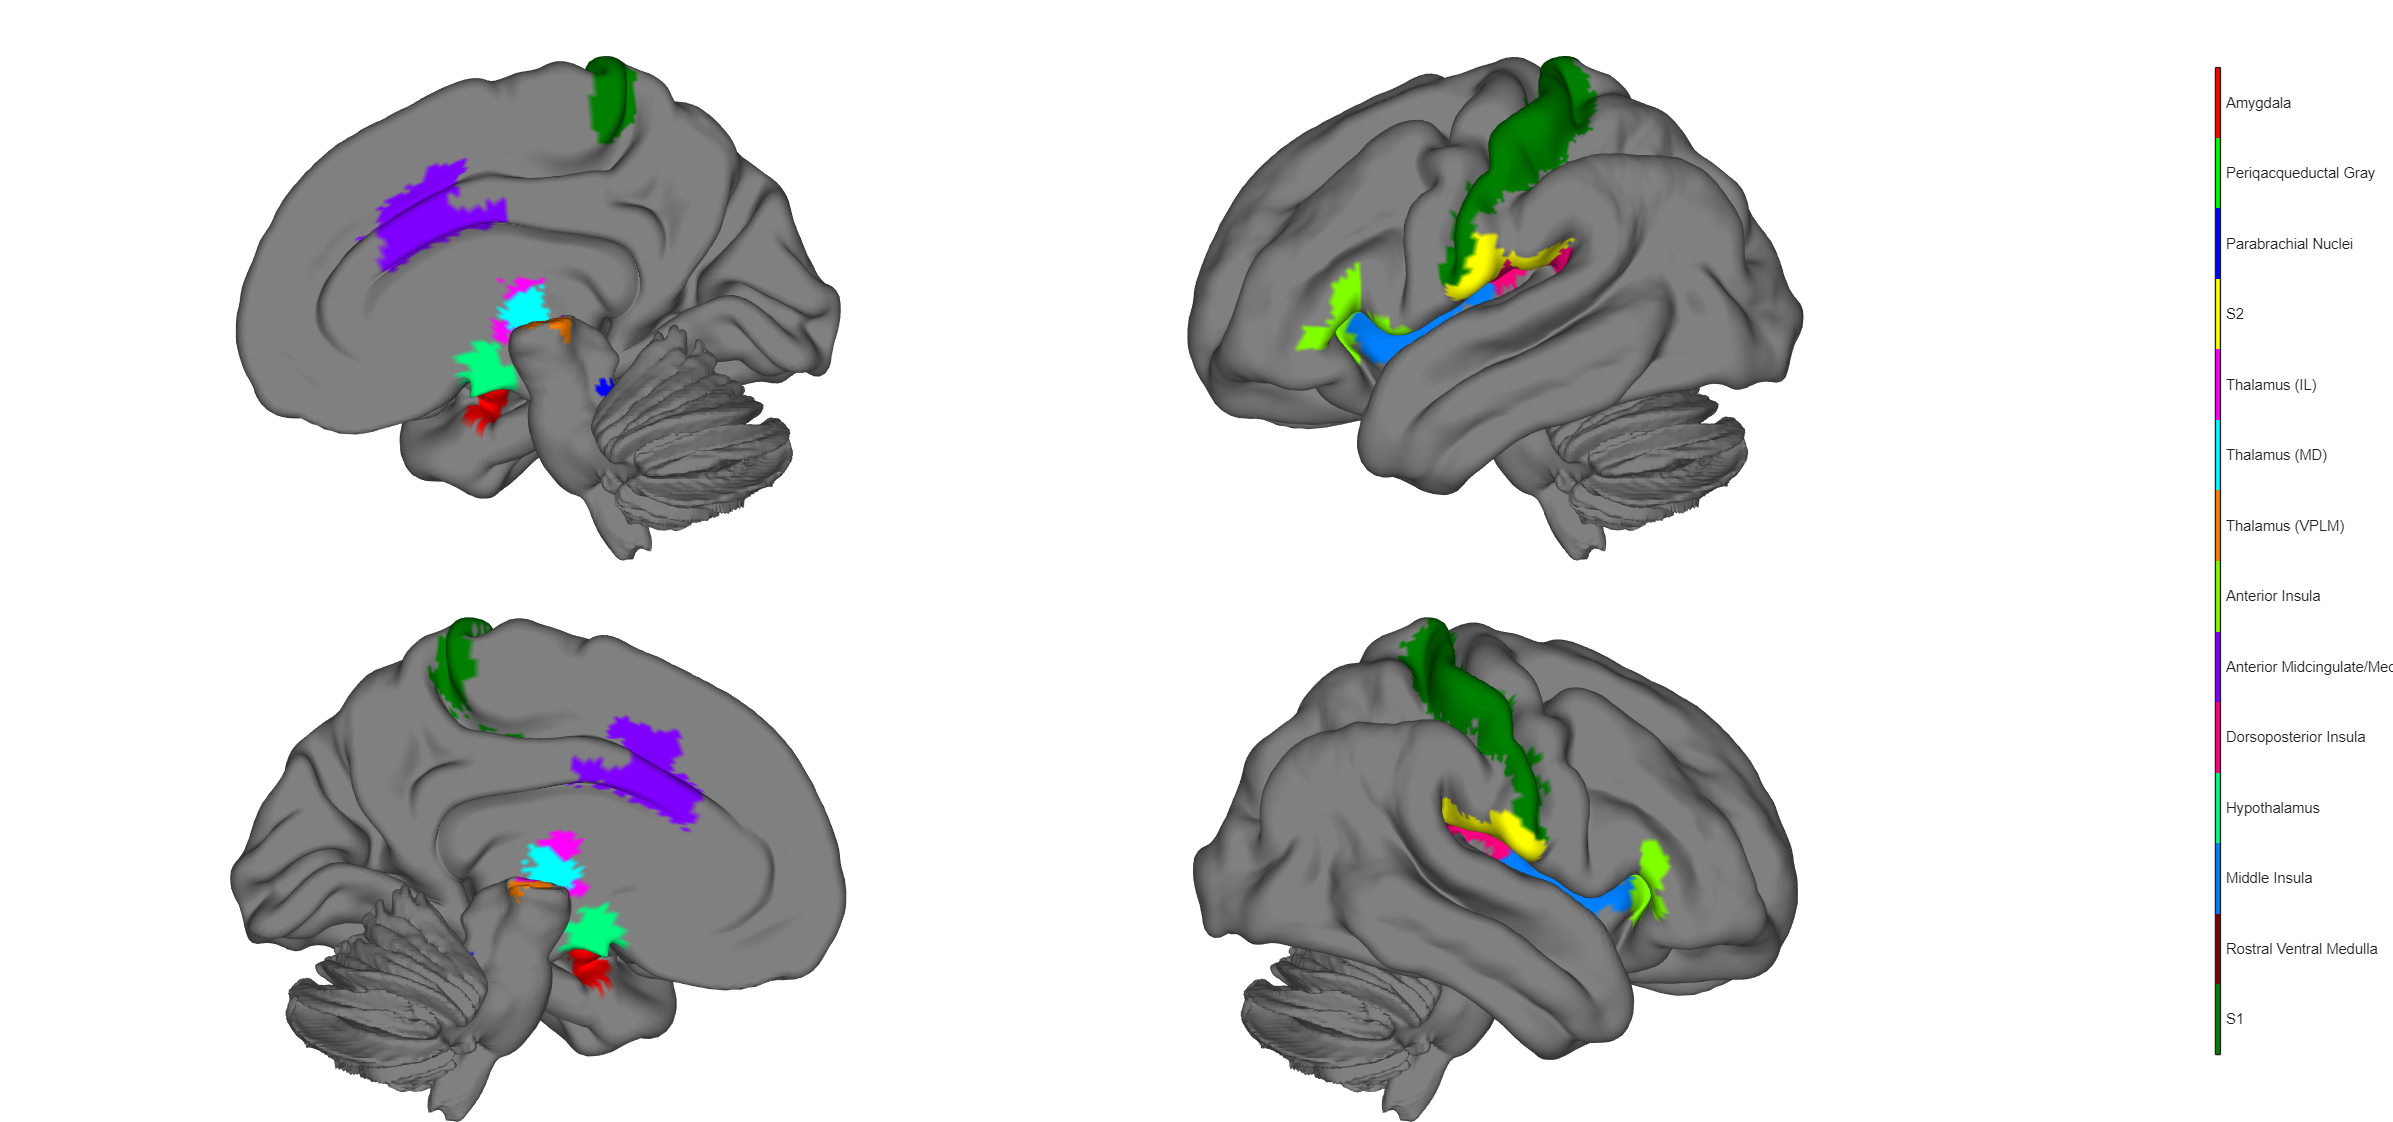

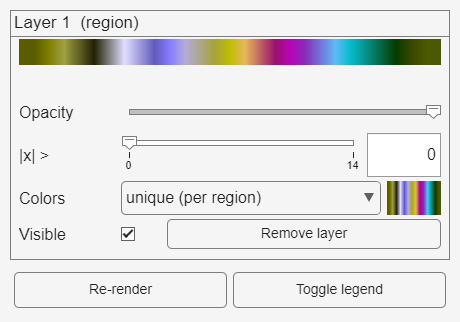

same_conditions = { ...

Compressed NIfTI files are not supported.


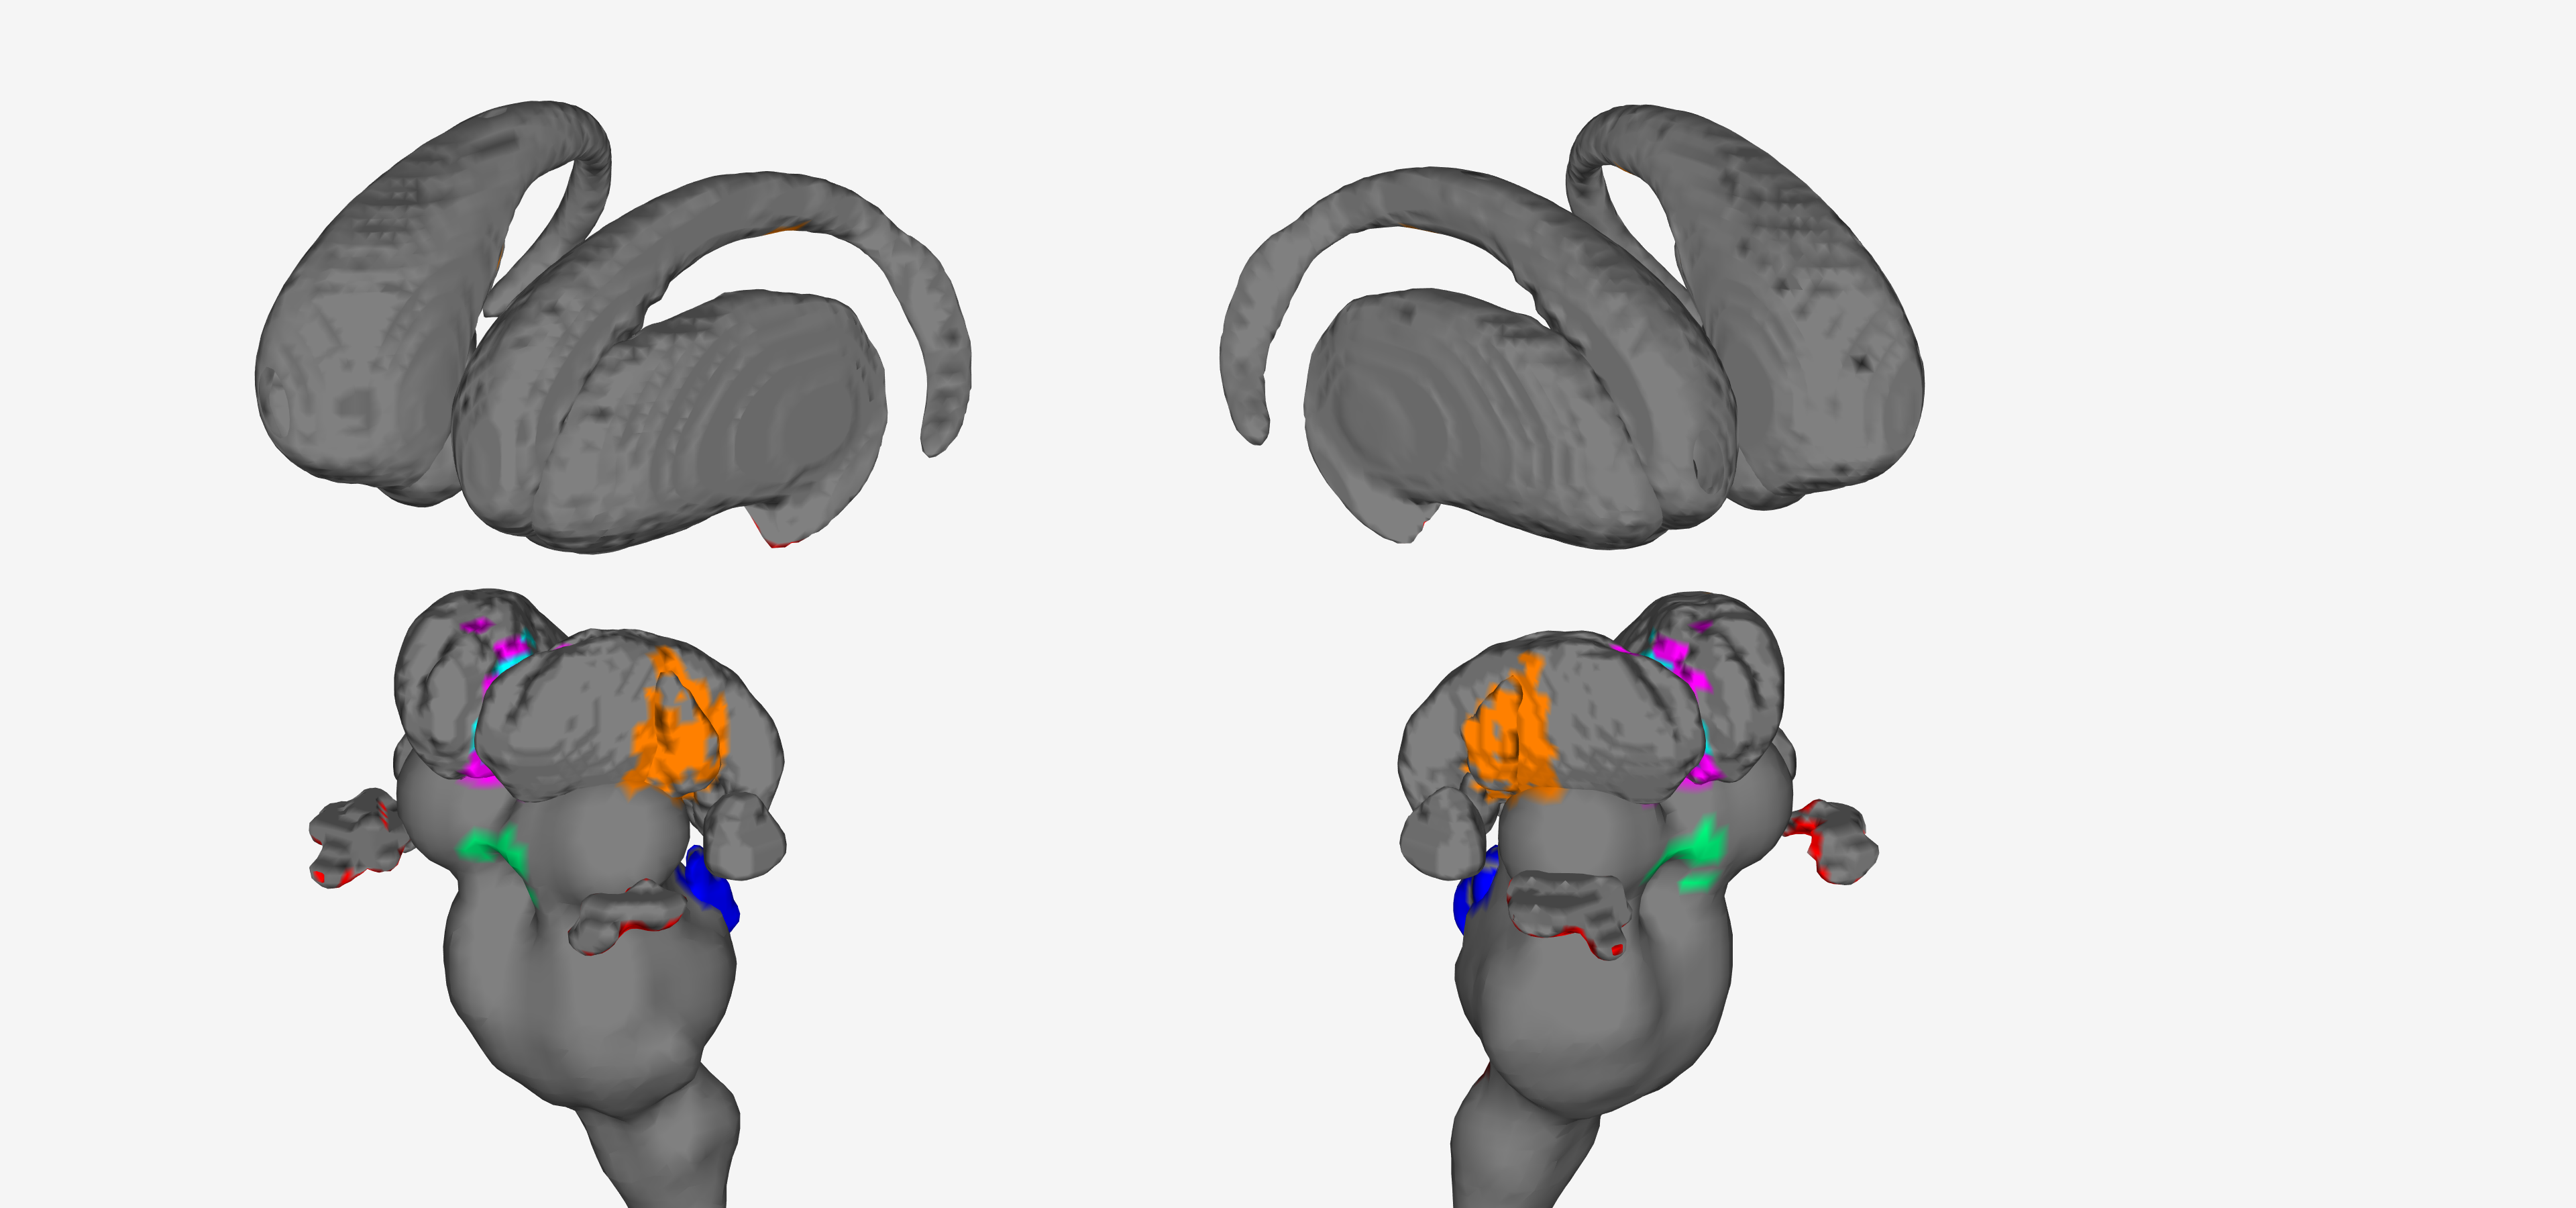

    'Hot-Rest: Same Body Site', ...
    'Warm-Rest: Same Body Site', ...

Compressed NIfTI files are not supported.


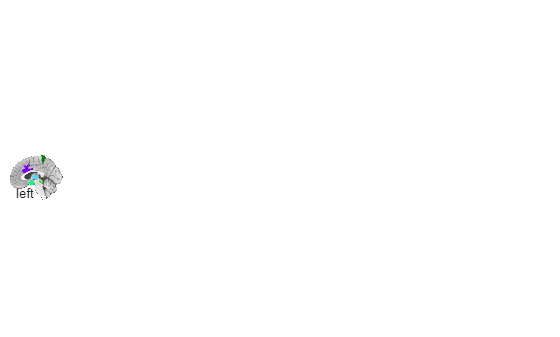

    'Imagine-Rest: Same Body Site'};

different_conditions = { ...

    'Hot-Rest: Different Body Site', ...
    'Warm-Rest: Different Body Site', ...
    'Imagine-Rest: Different Body Site'};

plot_subject_level_estimates(PainROIs_subject_results, ...
    unique_rois, same_conditions, different_conditions);
ylabel('Pattern Expression');
print(gcf, fullfile(svgdir, 'Figure_1_SVM_Barplot.svg'), '-dsvg', '-vector');   % vector SVG export

## Figure 5: A priori Regions of Interest from The Pain Pathways Atlas

These ROIs are identified and then bihemispherically merged from **load_atlas('pain_pathways2024')**.

labels={'Amygdala', 'Periqacqueductal Gray', 'Parabrachial Nuclei', 'S2', 'Thalamus (IL)', 'Thalamus (MD)', 'Thalamus (VPLM)', 'Anterior Insula', 'Anterior Midcingulate/Medial Prefrontal Cortex', 'Dorsoposterior Insula', 'Hypothalamus', 'Middle Insula', 'Rostral Ventral Medulla', 'S1'}
figure('Position', [0, 0, 2560, 1200]); PainROIs_atlas.montage('hcp', 'labels', labels, 'legend');
% print(gcf, fullfile(svgdir, 'Figure_S5_PainPathways_Cortex.svg'), '-dsvg', '-vector'); 

    Subject            ROI                          Condition                    Estimate         SE           T          Lower CI       Upper CI          P         Effect Size
    _______    ___________________    ______________________________________    ___________    ________    __________    ___________    ___________    __________    ___________

       1       Amygdala               Warm-Rest: Same Body Site                   -0.091916    0.029311       -3.1359       -0.14937      -0.034466     0.0017135       -0.68267
       1       Amygdala               Hot-Rest: Same Body Site                      0.15111    0.033086        4.5671       0.08

figure('Position', [0, 0, 2560, 1200]); PainROIs_atlas.montage('subcortex 3d', 'labels', labels);

    Subject                 ROI                                Condition                    Estimate         SE             T          Lower CI       Upper CI          P         Effect Size
    _______    ______________________________    ______________________________________    ___________    _________    ___________    ___________    ___________    __________    ___________

       1       55b                               Warm-Rest: Same Body Site                     -0.1462      0.04037        -3.6215       -0.22533      -0.067074    0.00029293       -0.63046
       1       55b                               Hot-Rest: Same Body Site                

% print(gcf, fullfile(svgdir, 'Figure_S5_PainPathways_Subcortex.svg'), '-dsvg', '-vector'); 

figure; PainROIs_atlas.montage('labels', labels, 'coordinates');

## Figure S6: 131 Region CANLab 2024 Atlas

These ROIs are identified and then bihemispherically merged from **load_atlas('canlab2024')**.

figure('Position', [0, 0, 2560, 1200]); canlab2024_atlas.montage('hcp inflated', 'labels', format_strings_for_legend(canlab2024_atlas.labels));
print(gcf, fullfile(svgdir, 'Figure_S6_CANLab2024_Cortex.svg'), '-dsvg', '-vector'); 
figure('Position', [0, 0, 2560, 1200]); canlab2024_atlas.montage('subcortex full', 'labels', format_strings_for_legend(canlab2024_atlas.labels), 'coordinates');
print(gcf, fullfile(svgdir, 'Figure_S6_CANLab2024_SubCortex.svg'), '-dsvg', '-vector'); 

## Subject-Level Data

**PainROIs_subject_results** and **Canlab2024_subject_results **contains a table containing subject-level data for each ROI from an a priori CANLab pain pathways atlas, and the CANLab2024 whole-brain atlas respectively.

disp(PainROIs_subject_results)
disp(Canlab2024_subject_results)

## Figure 5: Bar Plots

Subject-level data can be overlayed upon barplots like in the bar-plots of Figure 5. The left three plots for each ROI shows the Hot-Warm individualized pattern-classifier for Hot, Warm, and Imagine images for matching body-sites between image and classifier. The right shows Hot, Warm, and Imagine pattern expression for non-matching body-sites between image and classifier. 

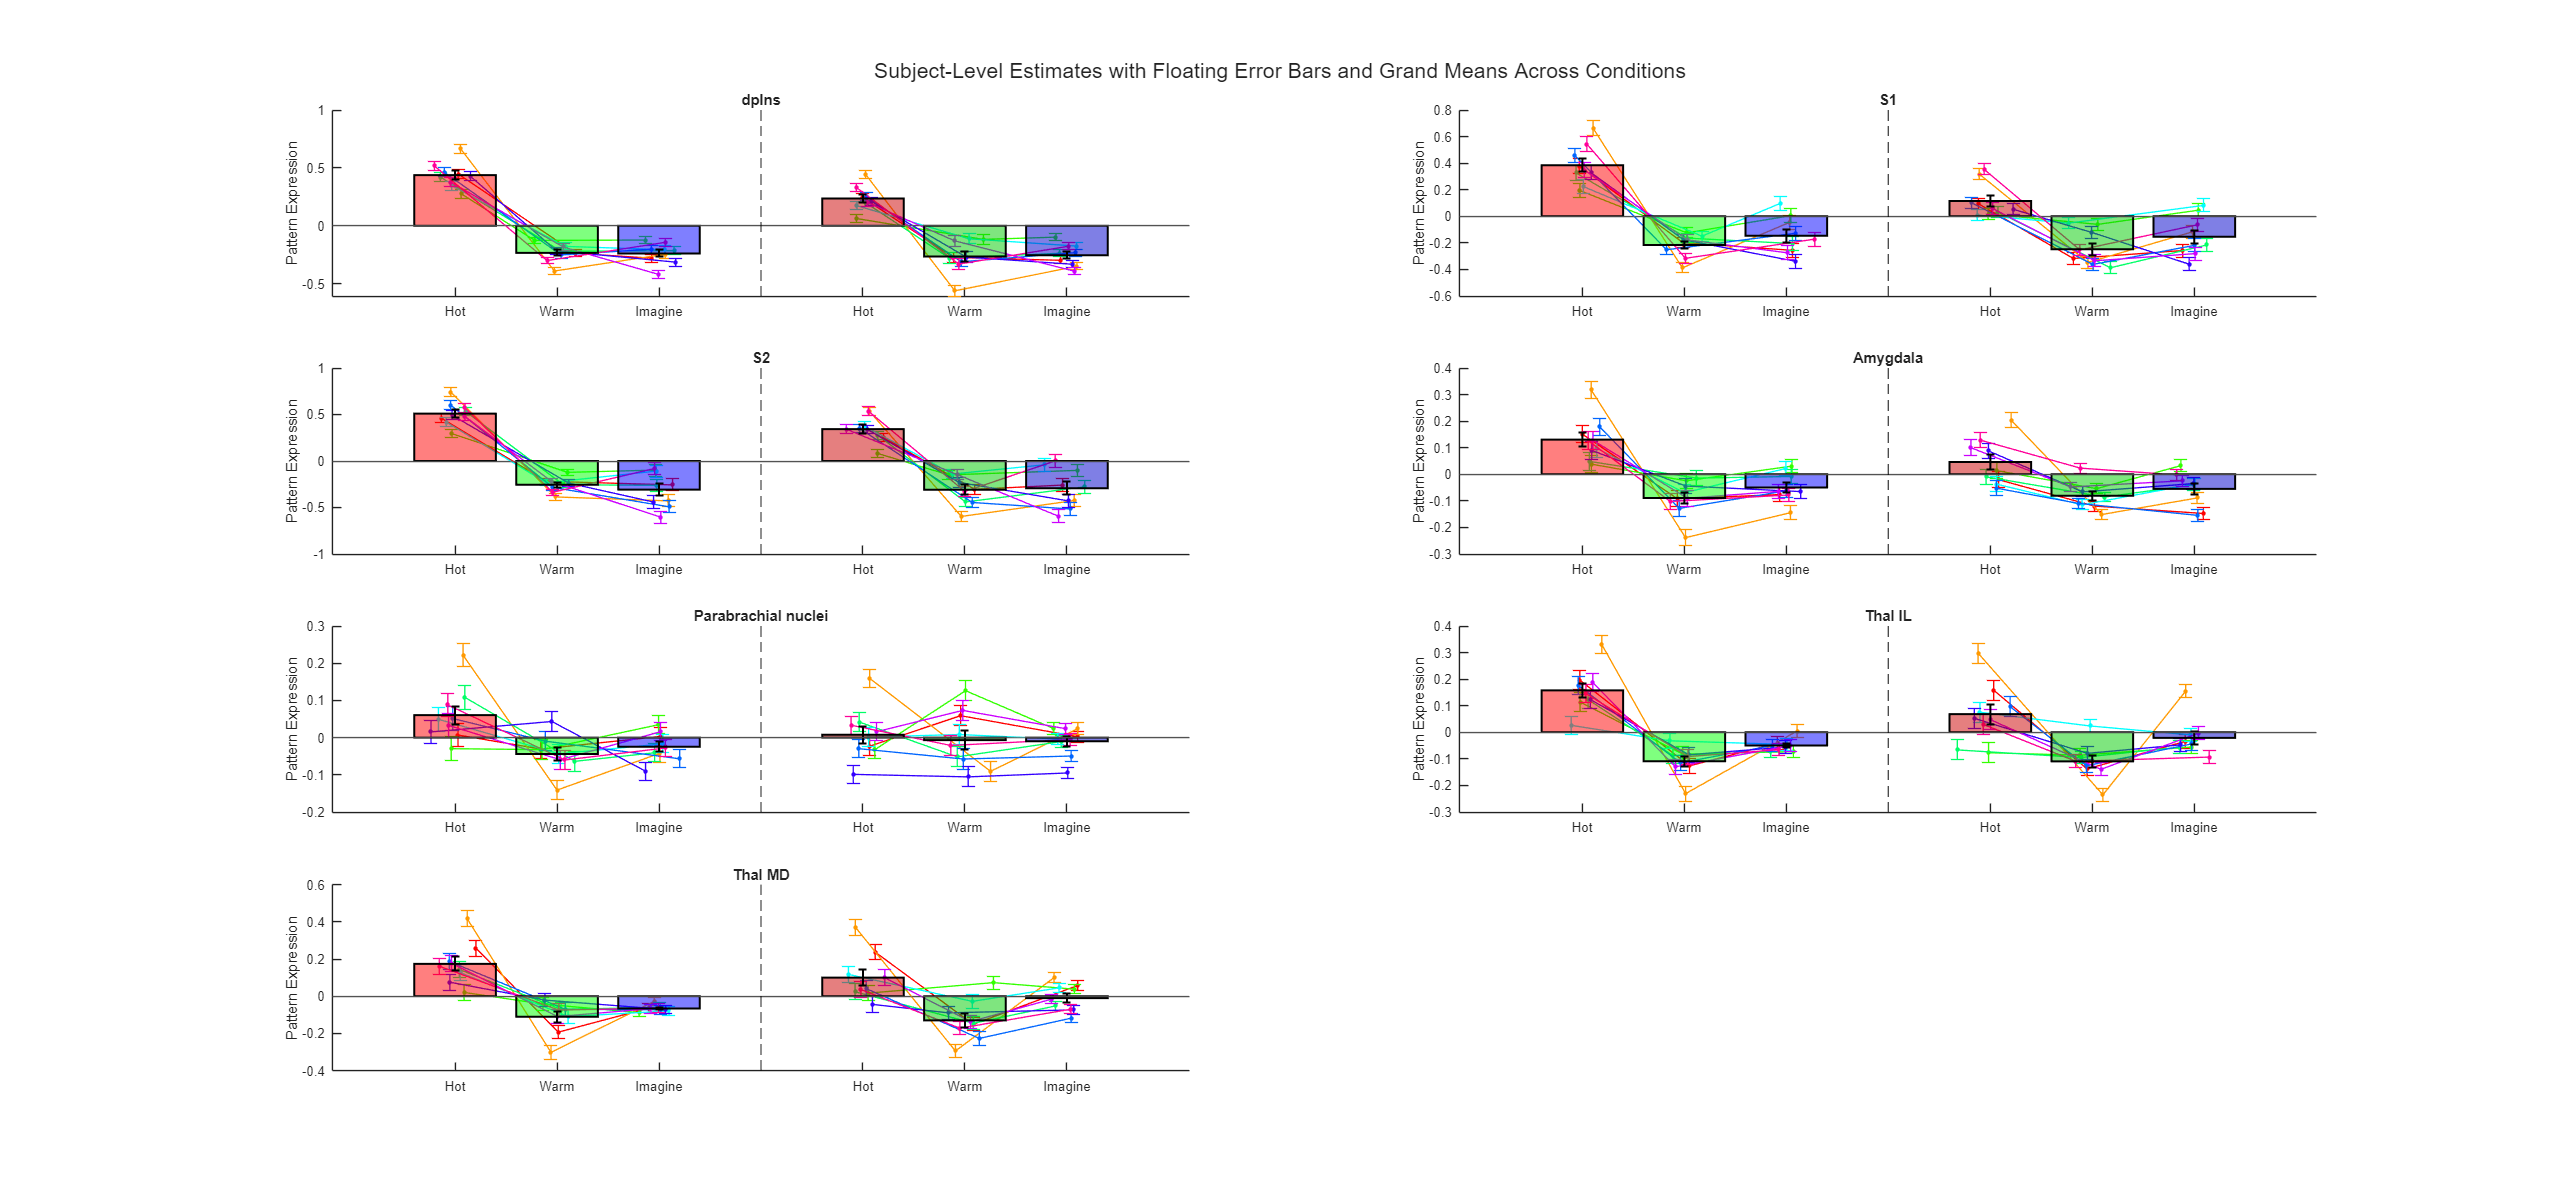

unique_rois = {'dpIns', 'S1', 'S2', 'Amygdala', ...
               'Parabrachial nuclei', 'Thal IL', 'Thal MD'};
same_conditions = { ...
    'Hot-Rest: Same Body Site', ...

    'Warm-Rest: Same Body Site', ...
    'Imagine-Rest: Same Body Site'};

different_conditions = { ...
    'Hot-Rest: Different Body Site', ...
    'Warm-Rest: Different Body Site', ...
    'Imagine-Rest: Different Body Site'};

plot_subject_level_estimates(PainROIs_subject_results, ...
    unique_rois, same_conditions, different_conditions);
ylabel('Pattern Expression');
print(gcf, fullfile(svgdir, 'Figure_5_SVM_Barplots.svg'), '-dsvg', '-vector');   % vector SVG export

## **Group-Level Data**

Group-level data for hypothesized contrasts can be found in the structs **PainROIs_results** and **Canlab2024_results**. Each of these structs contain the following fields:

- **HotSame: **A table containing the pattern expression for the Hot-Rest contrast for matching body-sites.

- **HWSame: **A table containing the pattern expression for the Hot-Warm contrast for matching body-sites.

- **HWSame_vDiffBS: **A table containing the pattern expression contrasts between the Hot-Warm contrast of matching body-sites vs. the Hot-Warm contrast of nonmatching body-sites.

- **ImagineSame: **A table containing the pattern expression for the Hot-Rest contrast for matching body-sites.

- **IWSame: **A table containing the pattern expression for the Hot-Warm contrast for matching body-sites.

- **IWSame_vDiffBS: **A table containing the pattern expression contrasts between the Imagine-Warm contrast of matching body-sites vs. the Imagine-Warm contrast of nonmatching body-sites.

## Figure 6A: Regions expressing Hot-Warm (Pink) and Body Site Specific Patterns (Red)

We can identify regions that express Hot-Warm classification patterns at the group-level (Pink) and Body Site specificity over and above that (Red) by first filtering each table from CANLab2024:

% FDR Corrected
hot_same_regs=Canlab2024_results.HotSame(Canlab2024_results.HotSame.('FDR P') < .05 & Canlab2024_results.HotSame.('Effect Size') > 0, :).ROI;
hw_same_regs=Canlab2024_results.HWSame(Canlab2024_results.HWSame.('FDR P') < .05 & Canlab2024_results.HWSame.('Effect Size') > 0, :).ROI;
hwbs_regs=Canlab2024_results.HWSame_vDiffBS(Canlab2024_results.HWSame_vDiffBS.('FDR P') < .05 & Canlab2024_results.HWSame_vDiffBS.('Effect Size') > 0, :).ROI;

Canlab2024_ExpPain=intersect(hot_same_regs, hw_same_regs);
Canlab2024_ExpPain_BSspecific=intersect(hot_same_regs, intersect(hw_same_regs, hwbs_regs));
Canlab2024_ExpPain=setdiff(Canlab2024_ExpPain, Canlab2024_ExpPain_BSspecific);

Then we identify the a-priori pain regions implicated and combine the regions together to make two full region lists.

hot_same_regs=PainROIs_results.HotSame(PainROIs_results.HotSame.P < .05 & PainROIs_results.HotSame.('Effect Size') > 0, :).ROI
hw_same_regs=PainROIs_results.HWSame(PainROIs_results.HWSame.P < .05 & PainROIs_results.HWSame.('Effect Size') > 0, :).ROI
hwbs_regs=PainROIs_results.HWSame_vDiffBS(PainROIs_results.HWSame_vDiffBS.P < .05 & PainROIs_results.HWSame_vDiffBS.('Effect Size') > 0, :).ROI
PainROIs_ExpPain=intersect(hot_same_regs, hw_same_regs)
PainROIs_ExpPain_BSspecific=intersect(hot_same_regs, intersect(hw_same_regs, hwbs_regs))

PainROIs_ExpPain_BSspecific_atlas=select_atlas_subset(PainROIs_atlas,  cellstr(PainROIs_ExpPain_BSspecific));
PainROIs_to_Canlab2024ROIs=apply_mask(canlab2024_2, PainROIs_ExpPain_BSspecific_atlas).label_table;
PainROIs_to_Canlab2024ROIs=strrep(PainROIs_to_Canlab2024ROIs.labels, '+', '');
PainROIs_to_Canlab2024ROIs=strrep(PainROIs_to_Canlab2024ROIs, '_', ' ');
Canlab2024_ExpPain_BSspecific = unique(vertcat(cellstr(Canlab2024_ExpPain_BSspecific),  PainROIs_to_Canlab2024ROIs));
Canlab2024_ExpPain_BSspecific = unique(cellstr(Canlab2024_ExpPain_BSspecific));

PainROIs_ExpPain_atlas=select_atlas_subset(PainROIs_atlas,  cellstr(PainROIs_ExpPain));
PainROIs_to_Canlab2024ROIs=apply_mask(canlab2024_2, PainROIs_ExpPain_atlas).label_table;
PainROIs_to_Canlab2024ROIs=strrep(PainROIs_to_Canlab2024ROIs.labels, '+', '');
PainROIs_to_Canlab2024ROIs=strrep(PainROIs_to_Canlab2024ROIs, '_', ' ');
Canlab2024_ExpPain = unique(vertcat(cellstr(Canlab2024_ExpPain),  PainROIs_to_Canlab2024ROIs));
Canlab2024_ExpPain = setdiff(Canlab2024_ExpPain, Canlab2024_ExpPain_BSspecific);

% Clean up the region labels so they match up properly
canlab2024_regionlist = canlab2024_2.labels;
canlab2024_regionlist = strrep(canlab2024_regionlist , '+', '');
canlab2024_regionlist = strrep(canlab2024_regionlist , '_', ' ');
canlab2024_regionlist = strrep(canlab2024_regionlist , '-', ' ');

canlab2024_atlas.labels = canlab2024_regionlist;

r=canlab2024_regionlist(find(ismember(canlab2024_regionlist, Canlab2024_ExpPain)));
r1=[r{:}];
r=canlab2024_regionlist(find(ismember(canlab2024_regionlist, Canlab2024_ExpPain_BSspecific)));
r2=[r{:}];

Now we plot it:

Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 132  Bit rate: 7.04 bits


Setting up fmridisplay objects
Compressed NIfTI files are not supported.
    48



sagittal montage: 29821 voxels displayed, 162947 not displayed on these slices


coronal montage: 29193 voxels displayed, 163575 not displayed on these slices


axial montage: 39746 voxels displayed, 153022 not displayed on these slices


axial montage: 39187 voxels displayed, 153581 not displayed on these slices


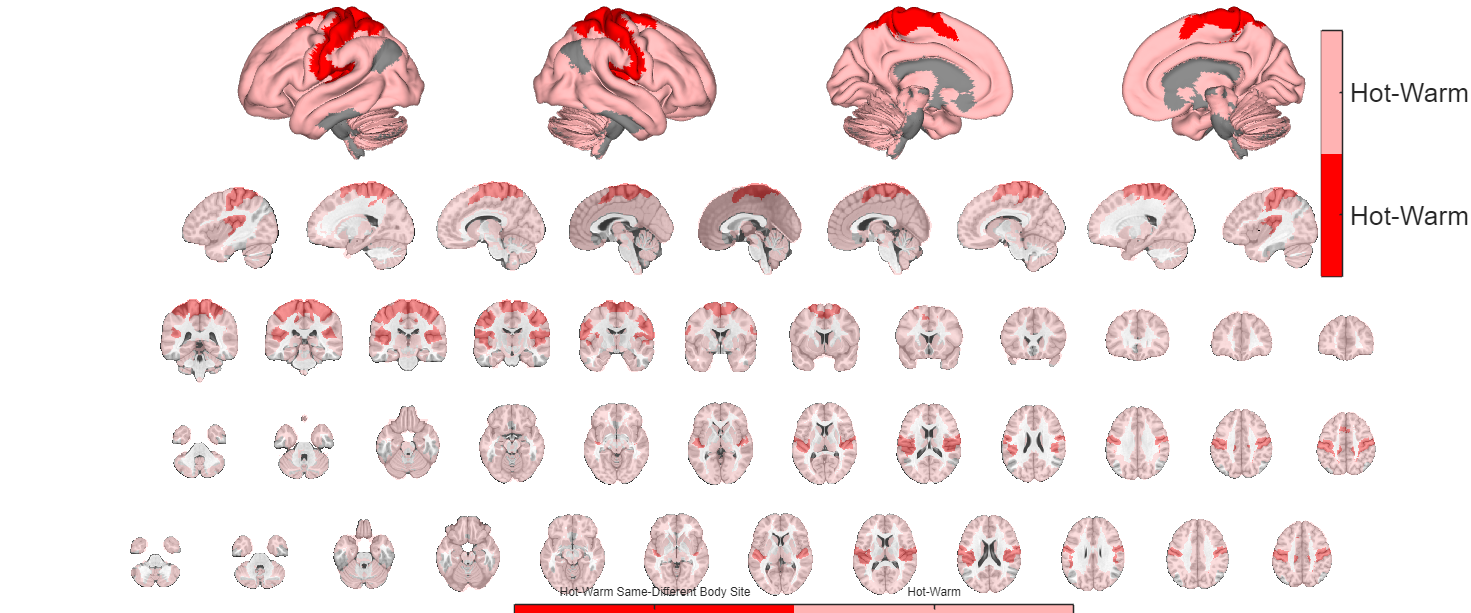

colors=seaborn_colors(30);

Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 132  Bit rate: 7.04 bits


Setting up fmridisplay objects
Compressed NIfTI files are not supported.


sagittal montage: 21275 voxels displayed, 171493 not displayed on these slices


coronal montage: 16236 voxels displayed, 176532 not displayed on these slices


axial montage: 19565 voxels displayed, 173203 not displayed on these slices


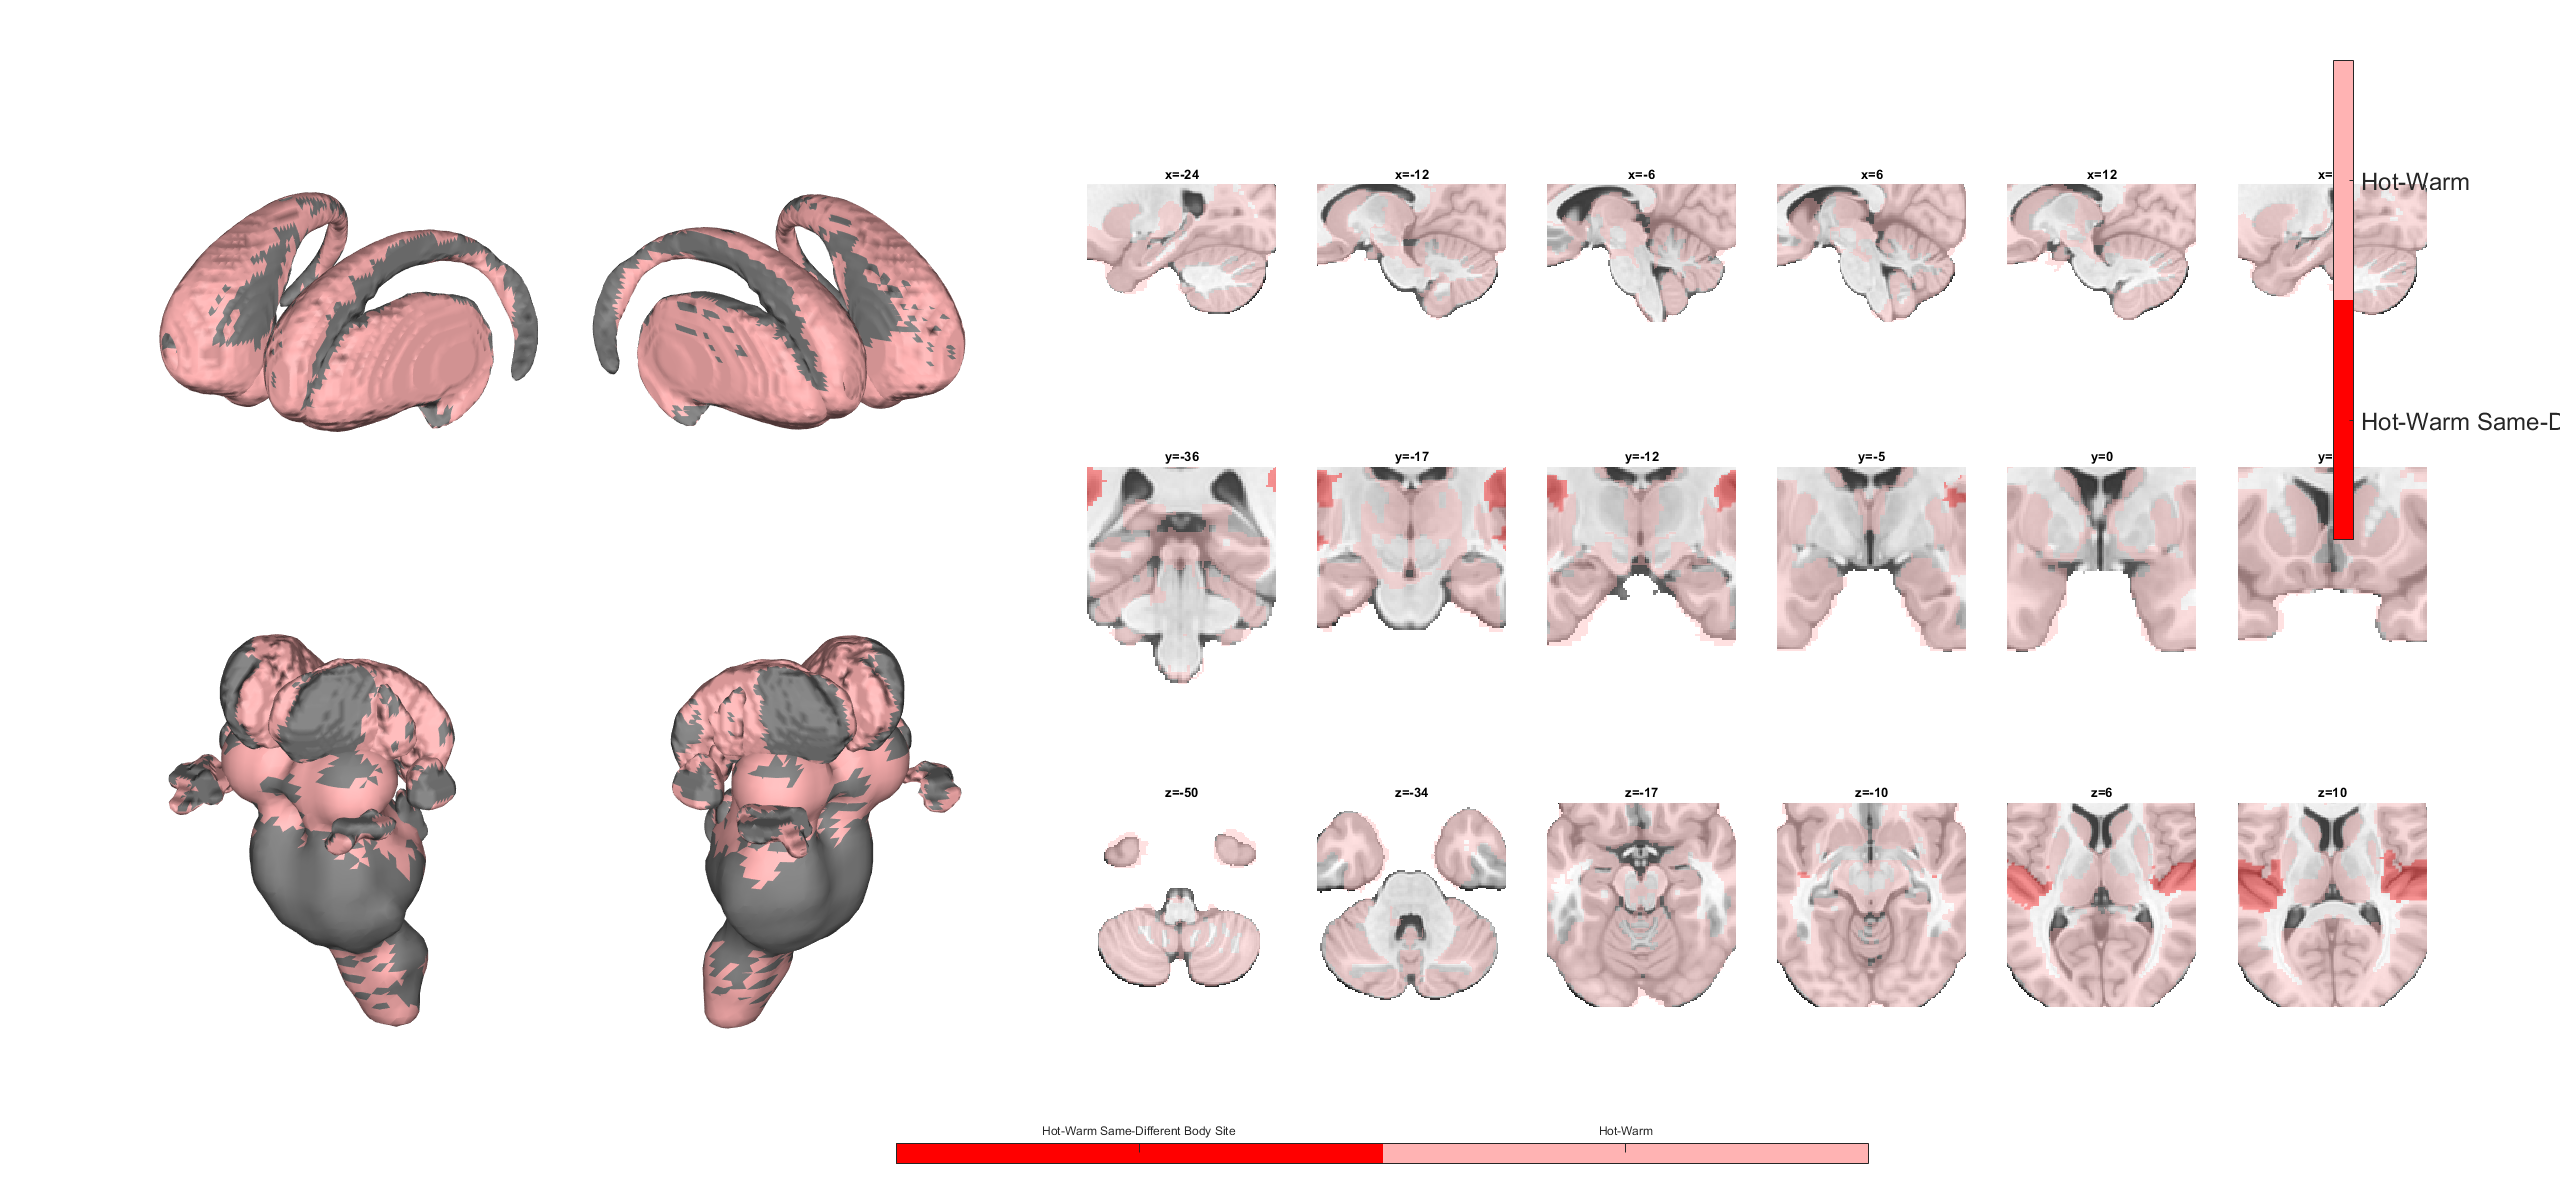

pink_color={[1 .7 .7]};

red_color={[1 0 0]};
cm = vertcat(red_color{:}, pink_color{:});

figure('Position', [0, 0, 2560, 1200]); assign_vals(canlab2024_atlas, 'interp', 'linear', 'reg_names', cellstr(vertcat(Canlab2024_ExpPain_BSspecific, Canlab2024_ExpPain)), 'vals', [repmat(1, size(Canlab2024_ExpPain_BSspecific)); repmat(2, size(Canlab2024_ExpPain))]).montage('full hcp', 'indexmap', cm, 'labels', {'Hot-Warm Same-Different Body Site', 'Hot-Warm'}, 'trans', 'transvalue', .4);
figure('Position', [0, 0, 2560, 1200]); assign_vals(canlab2024_atlas, 'reg_names', cellstr(vertcat(Canlab2024_ExpPain_BSspecific, Canlab2024_ExpPain)), 'vals', [repmat(1, size(Canlab2024_ExpPain_BSspecific)); repmat(2, size(Canlab2024_ExpPain))]).montage('subcortex full', 'indexmap', cm, 'labels', {'Hot-Warm Same-Different Body Site', 'Hot-Warm'}, 'trans', 'transvalue', .4);

## Figure 6B; Somatotopic Effect Size Map (Effect of Same BS vs. Different BS in pre-selected ROIs)

data = Canlab2024_results.HWSame_vDiffBS;

Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 132  Bit rate: 7.04 bits


Setting up fmridisplay objects
Compressed NIfTI files are not supported.


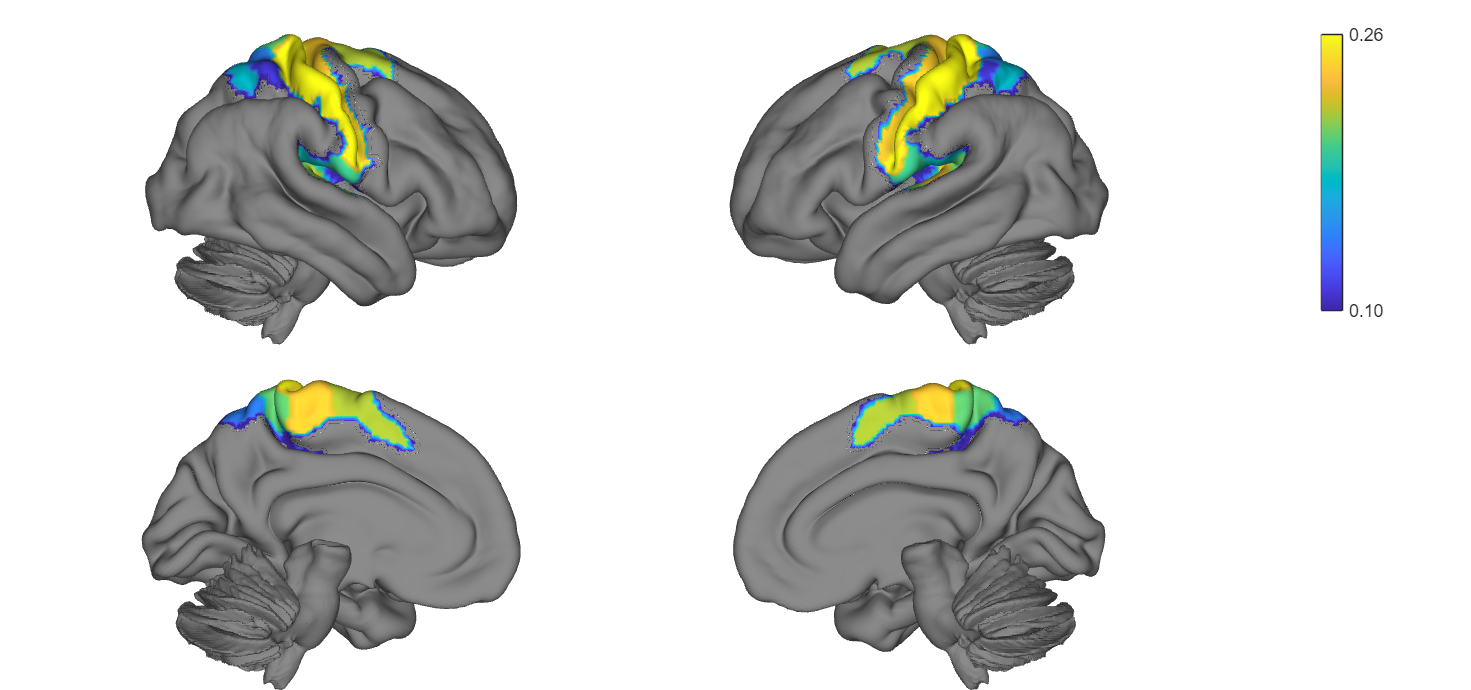

data = data(ismember(data.ROI, Canlab2024_ExpPain_BSspecific),:);

vals = data.('Effect Size');

[hw_somato, hw_somato_effect_tbl]=assign_vals(canlab2024_2, 'reg_names', cellstr(Canlab2024_ExpPain_BSspecific), 'vals', vals);
figure('Position', [0, 0, 2560, 1200]); hw_somato.montage('hcp', 'colormap', parula);

## Figure 6C: Hot-Warm Body-Site Selective Regional Participant Countmaps

data = Canlab2024_results.HWSame_vDiffBS;
vals = data.('Significant Number of Subjects');

% Categorical Colormap
bright_colormap=flipud(cbrewer2('YlOrRd', 9));
dark_colormap=cbrewer2('GnBu', 9);

bright_colormap=flipud(bright_colormap);
dark_colormap=flipud(dark_colormap);


Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 132  Bit rate: 7.04 bits


Setting up fmridisplay objects
Compressed NIfTI files are not supported.


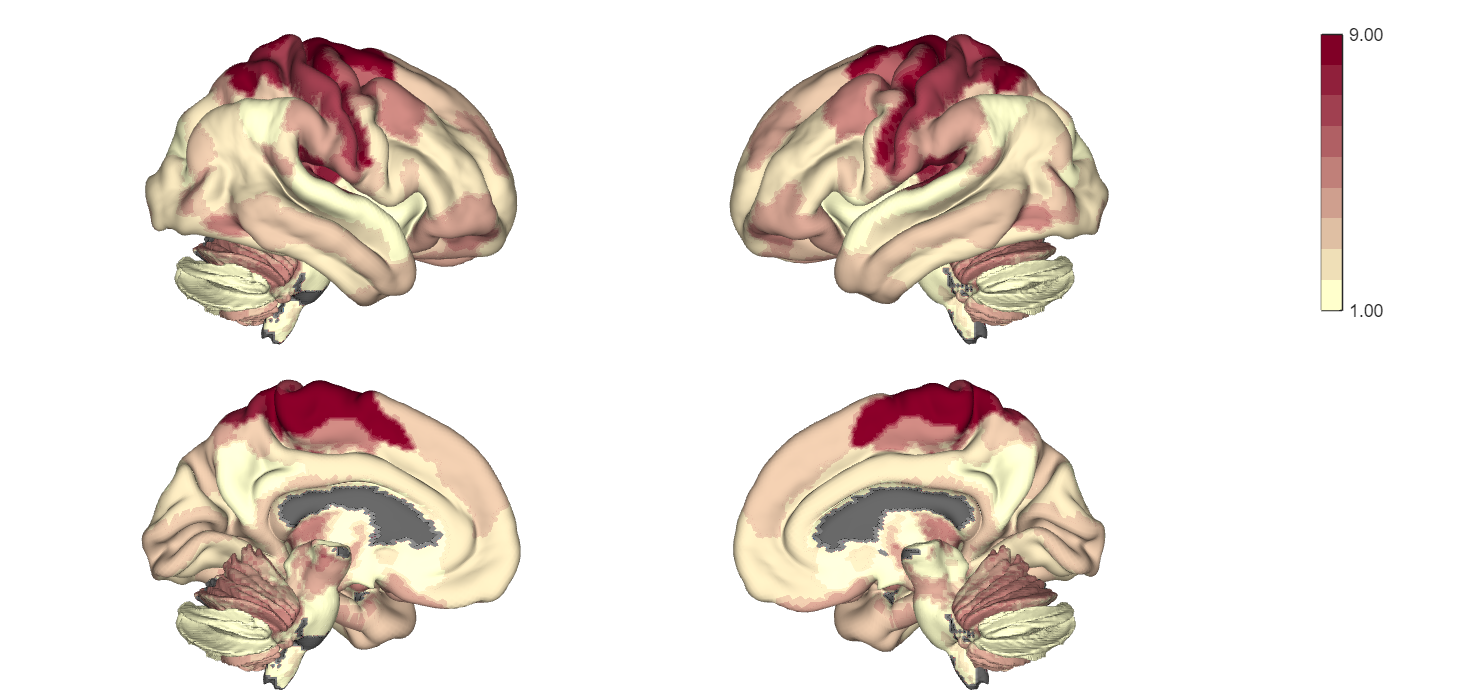

% figure

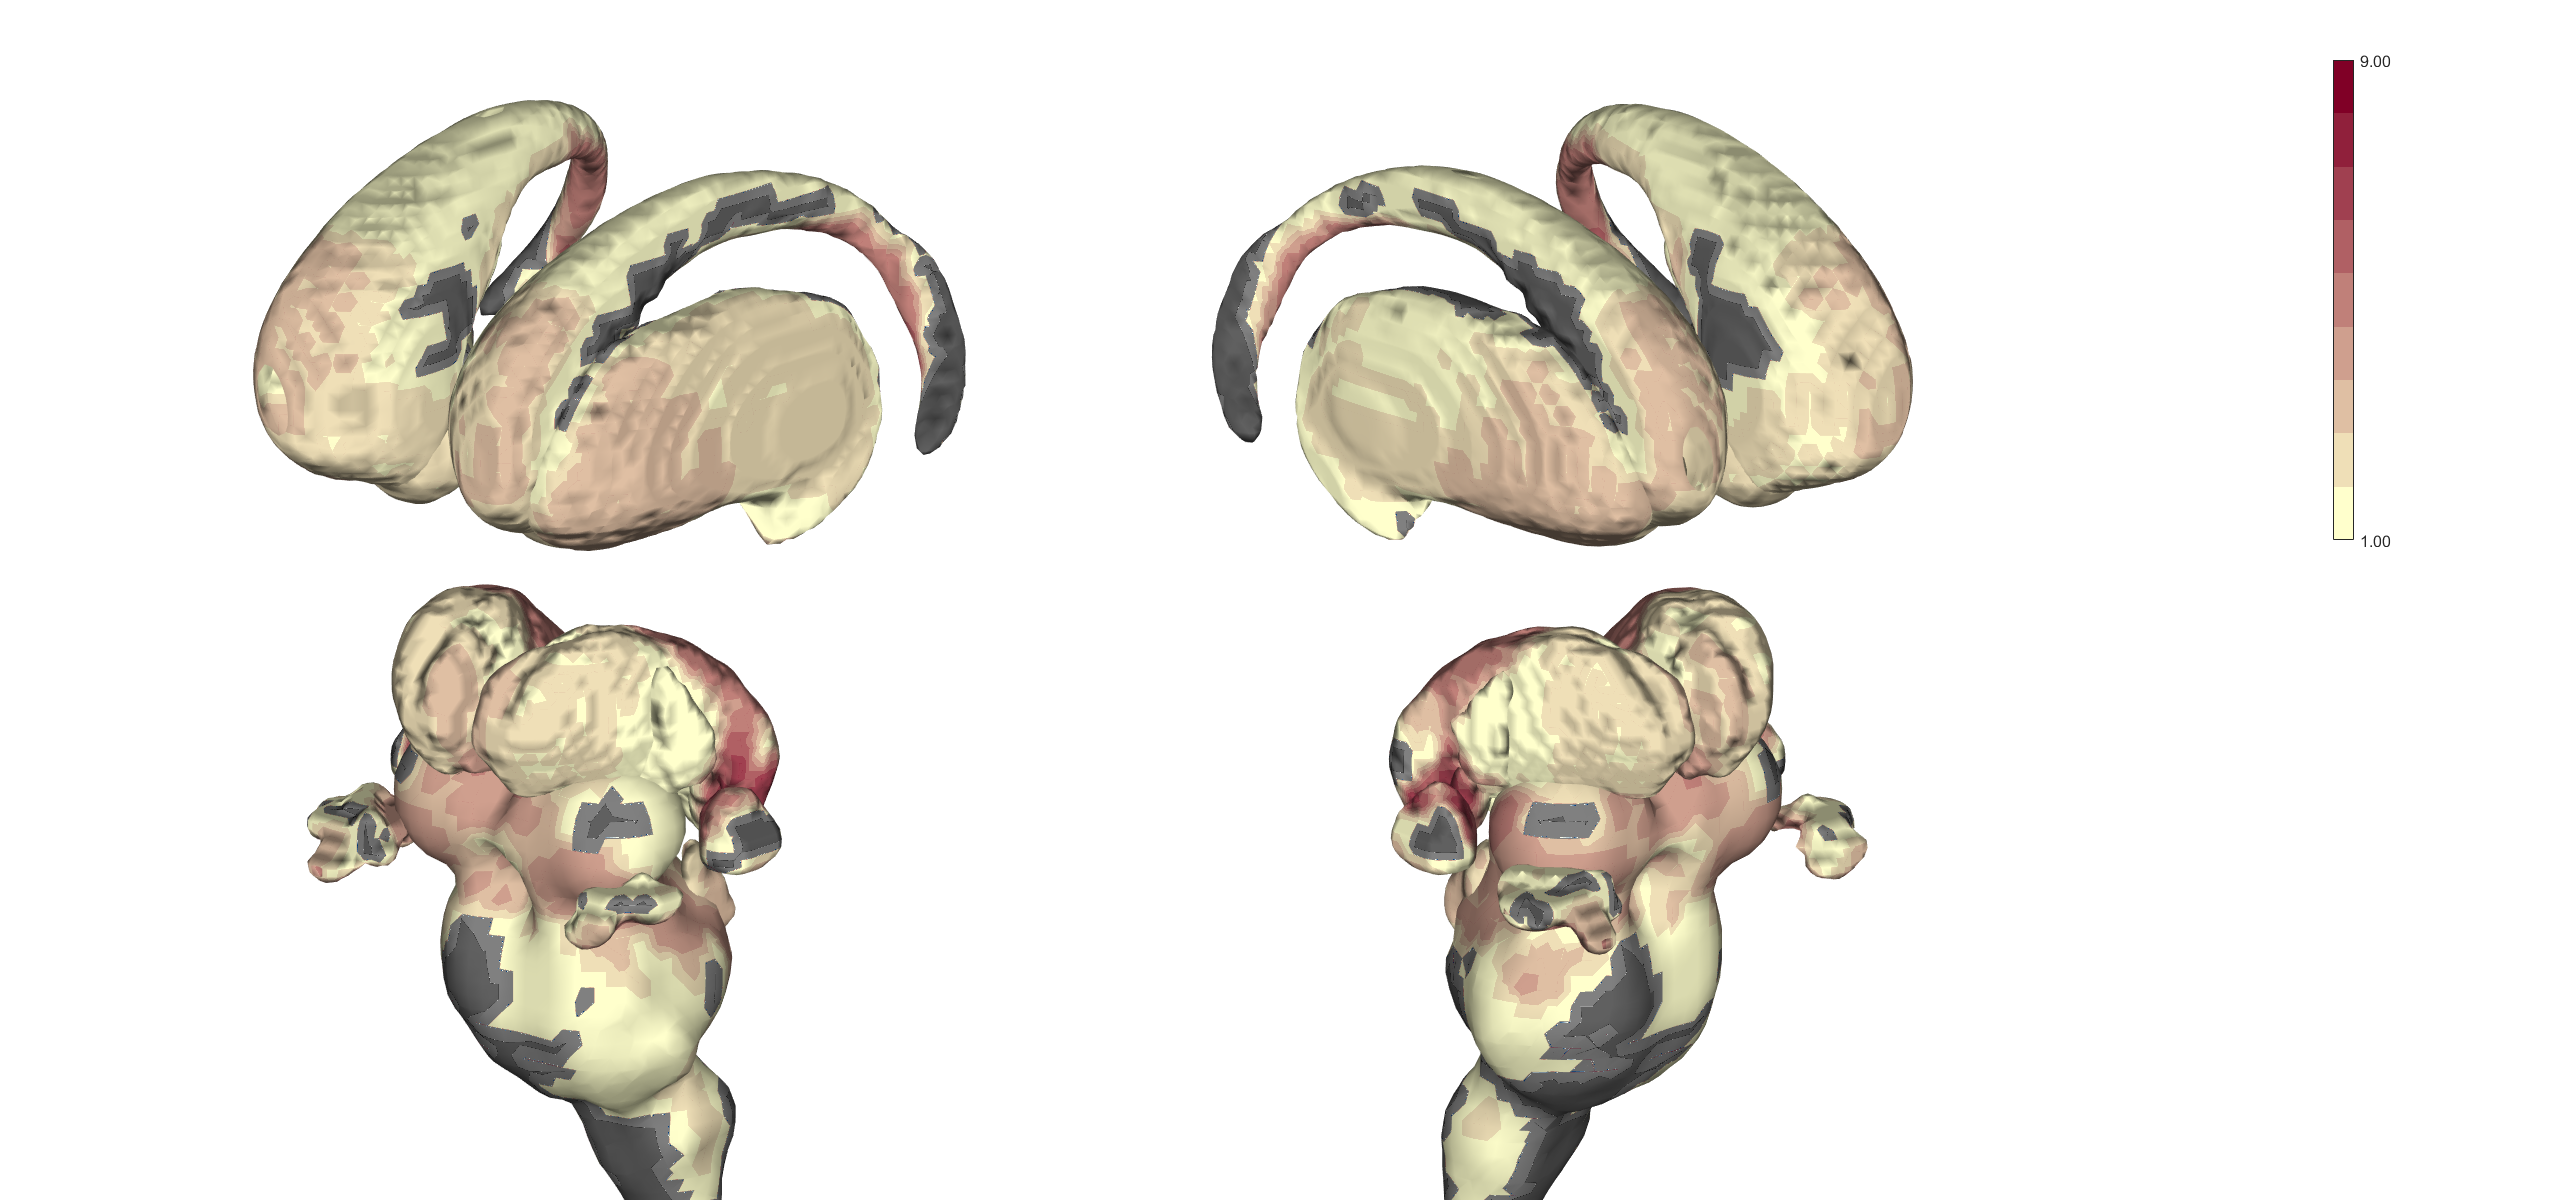

Setting up fmridisplay objects
Compressed NIfTI files are not supported.


cmap=[dark_colormap; [0,0,0]; bright_colormap];


[sub_hw_somato, sub_hw_somato_effect_tbl]=assign_vals(canlab2024_2, 'reg_names', cellstr(data.ROI), 'vals', vals);
figure('Position', [0, 0, 2560, 1200]); sub_hw_somato.montage('hcp', 'clim', [1 9], 'pos_colormap', bright_colormap, 'neg_colormap', dark_colormap, 'interp', 'linear', 'gray_buffer', false);
figure('Position', [0, 0, 2560, 1200]);
o2 = sub_hw_somato.montage('subcortex 3d', 'clim', [1 9], 'pos_colormap', bright_colormap, 'neg_colormap', dark_colormap, 'trans', 'transvalue', .4,  'sourcespace', 'MNI152NLin2009cAsym', 'targetsurface', 'fsaverage_164k','interp', 'linear', 'gray_buffer', false);

## Figure 6D: Hot-Warm Somatotopic Maps

Since all body site specific regions are on the cortex, we can achieve much better fine-grained understanding of the body site specificity of each parcel using surface CIFTI data. The CIFTI data included here

- **canlab2024_cifti: **The CANLab 2024 Atlas in CIFTI structure format.

- **leftdata_hw_bsgrpavg: **Cell-array of group-level averaged vertex-data for the Hot-Warm BOLD contrast in the left hemisphere. Each cell corresponds to one of eight body sites: Left Face, Right Face, Left AArm, Righit Arm, Left Leg, Right Leg, Chest, and Abdomen.

- **rightdata_hw_bsgrpavg: **Cell-array of group-level averaged vertex-data for the Hot-Warm BOLD contrast in the right hemisphere. Each cell corresponds to one of eight body sites: Left Face, Right Face, Left AArm, Righit Arm, Left Leg, Right Leg, Chest, and Abdomen.

To use the cifti data, we first do some housekeeping to match up each vertex with a region label.

canlab2024_518atlas = load_atlas('canlab2024');

Loading atlas: CANLab2024_MNI152NLin2009cAsym_coarse_2mm_atlas_object.mat



% Mask out the hw_somato regions created above from canlab2024
hw_labels=apply_mask(canlab2024_518atlas, hw_somato).label_table;
idx = ismember(canlab2024_518atlas.label_table.labels, hw_labels.labels);

% Display indices and matched labels
matched_labels = unique(canlab2024_518atlas.label_table.labels_2(idx));
canlab2024_cifti_labels=table(string({canlab2024_cifti.ciftidat.diminfo{2}.maps.table.name})', ...
    cell2mat({canlab2024_cifti.ciftidat.diminfo{2}.maps.table.key})', 'VariableNames', {'labels', 'label_idx'});

canlab2024_labels=canlab2024.label_table;

Then we generate the CIFTI masks

hw_somato_idx=canlab2024_cifti_labels(ismember(canlab2024_cifti_labels.labels, canlab2024_labels(idx,:).labels),:).label_idx;
hw_somato_leftmask=ismember(canlab2024_cifti.cortex_left', hw_somato_idx);
hw_somato_rightmask=ismember(canlab2024_cifti.cortex_right', hw_somato_idx);

Now we concatenate the activations from each of the 8 body sites, and generate a Winner-Take-All map.

leftdata_bshw=[leftdata_hw_bsgrpavg{1}', ...
 leftdata_hw_bsgrpavg{2}', ...
 leftdata_hw_bsgrpavg{3}', ...
 leftdata_hw_bsgrpavg{4}', ...
 leftdata_hw_bsgrpavg{5}', ...
 leftdata_hw_bsgrpavg{6}', ...
 leftdata_hw_bsgrpavg{7}', ...
 leftdata_hw_bsgrpavg{8}'];

rightdata_bshw=[rightdata_hw_bsgrpavg{1}', ...
 rightdata_hw_bsgrpavg{2}', ...
 rightdata_hw_bsgrpavg{3}', ...
 rightdata_hw_bsgrpavg{4}', ...
 rightdata_hw_bsgrpavg{5}', ...
 rightdata_hw_bsgrpavg{6}', ...
 rightdata_hw_bsgrpavg{7}', ...
 rightdata_hw_bsgrpavg{8}'];

leftdata_hw_wta=winnerTakeAll(leftdata_bshw);
rightdata_hw_wta=winnerTakeAll(rightdata_bshw);

% Mask out only the relevant regions
leftdata_hw_wta(~hw_somato_leftmask)=0;
rightdata_hw_wta = rightdata_hw_wta;
rightdata_hw_wta(~hw_somato_rightmask)=0;

Now we plot it, using a custom **plot_to_surf()** method made by Bogdan Petre to plot the vertex data on the surface.

figure('Position', [0, 0, 2560, 1200]);
o2 = canlab_results_fmridisplay('hcp');

Setting up fmridisplay objects
Compressed NIfTI files are not supported.


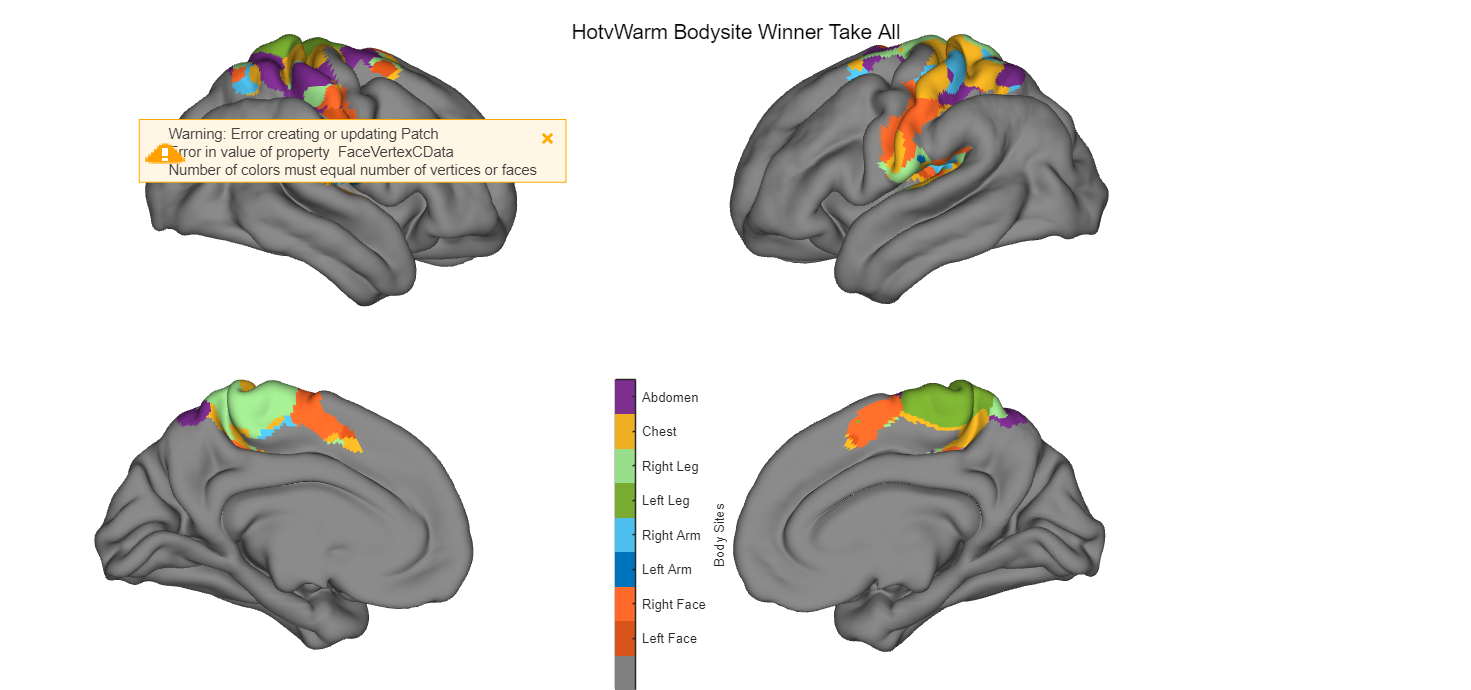


% Left Hemisphere Plot
plot_to_surf(leftdata_hw_wta', o2.surface{4}.object_handle, 'indexmap', 'colormap', cmap);
plot_to_surf(leftdata_hw_wta', o2.surface{2}.object_handle, 'indexmap', 'colormap', cmap);

% Right Hemisphere Plot
plot_to_surf(rightdata_hw_wta', o2.surface{1}.object_handle, 'indexmap', 'colormap', cmap);
plot_to_surf(rightdata_hw_wta', o2.surface{3}.object_handle, 'indexmap', 'colormap', cmap);

% Set the title
sgtitle('HotvWarm Bodysite Winner Take All');

bodysite_colorbar

## Save

save('PrecisionSVM_Results_Workspace.mat', 'PainROIs_subject_results', 'Canlab2024_subject_results', 'PainROIs_results', 'Canlab2024_results', 'canlab2024_cifti', 'leftdata_hw_bsgrpavg', 'rightdata_hw_bsgrpavg')

## Functions

function plot_subject_level_estimates(subject_results, unique_rois, same_conditions, different_conditions, varargin)
% PLOT_SUBJECT_LEVEL_ESTIMATES
%
% Plots subject-level estimates with floating error bars and grand means
% for a table with columns:
%   Subject, ROI, Condition, Estimate, SE
%
% INPUTS
%   subject_results      : table with the columns above (+ others)
%   unique_rois          : cellstr of ROIs to plot
%   same_conditions      : cellstr of 3 "Same bodysite" condition names
%   different_conditions : cellstr of 3 "Different bodysite" condition names
%   (optional) subjID    : vector of subject indices to highlight (thicker lines)
%
% Example condition lists for your finalized table:
%   same_conditions = {
%       'Hot-Rest: Same Body Site', ...
%       'Warm-Rest: Same Body Site', ...
%       'Imagine-Rest: Same Body Site'};
%   different_conditions = {
%       'Hot-Rest: Different Body Site', ...
%       'Warm-Rest: Different Body Site', ...
%       'Imagine-Rest: Different Body Site'};

    if ~isempty(varargin)
        subjID = varargin{1};
    else
        subjID = [];
    end

    % Make sure ROI is categorical (easier equality)
    if ~iscategorical(subject_results.ROI)
        subject_results.ROI = categorical(subject_results.ROI);
    end

    % Unique subjects (keep stable order)
    unique_subjects = unique(subject_results.Subject, 'stable');
    num_subjects    = numel(unique_subjects);

    % Color map for subjects
    subject_colors = hsv(10);
    subject_colors = subject_colors([1:2,4:end], :);

    % Condition order for grand means
    all_conditions = [same_conditions(:); different_conditions(:)]';

    % X positions
    nSame = numel(same_conditions);
    nDiff = numel(different_conditions);

    x_positions_same = 1:nSame;
    x_positions_diff = (nSame+2) : (nSame+1+nDiff);  % gap at x = nSame+1
    x_positions      = [x_positions_same, x_positions_diff];

    % For the vertical separator line
    if nDiff > 0
        sep_x = nSame + 1;
    else
        sep_x = [];
    end

    % Jitter in x
    jitter_sd = 0.1;

    % Figure
    figure('Position', [0 0 2560 1200], 'Color', 'w');

    % Loop over ROIs
    for r = 1:numel(unique_rois)
        roi = unique_rois{r};

        % Subset data for this ROI
        roi_data = subject_results(subject_results.ROI == roi, :);

        % Grand means and SEs per condition
        grand_means = nan(1, numel(all_conditions));
        grand_se    = nan(1, numel(all_conditions));

        for c = 1:numel(all_conditions)
            cond_name = all_conditions{c};
            idx = strcmp(string(roi_data.Condition), cond_name);
            cond_data = roi_data(idx, :);

            if ~isempty(cond_data)
                grand_means(c) = mean(cond_data.Estimate, 'omitnan');
                grand_se(c)    = std(cond_data.Estimate, 'omitnan') ./ sqrt(height(cond_data));
            end
        end

        % ---- Subplot ----
        subplot(ceil(numel(unique_rois)/2), 2, r);
        hold on;

        title(roi, 'Interpreter', 'none');
        yline(0, '-', 'Color', [0.4 0.4 0.4]);  % zero line

        if ~isempty(sep_x)
            xline(sep_x, '--k', 'LineWidth', 1.0);  % Same vs Different divider
        end

        % ------------------------------
        % Subject-level: Same Bodysite
        % ------------------------------
        for s = 1:num_subjects
            sid = unique_subjects(s);
            idx_sub = roi_data.Subject == sid;

            sub_data_same = roi_data(idx_sub & ...
                ismember(string(roi_data.Condition), same_conditions), :);

            if isempty(sub_data_same)
                continue;
            end

            % Sort rows to match same_conditions order
            condLabels = cellstr(string(sub_data_same.Condition));
            [~, ord]   = sort(ismember(same_conditions, condLabels)); %#ok<ASGLU>
            % Better: map each row to index in same_conditions and sort by that
            [~, idx_order] = ismember(condLabels, same_conditions);
            [~, sortIdx]   = sort(idx_order);
            sub_data_same  = sub_data_same(sortIdx, :);

            % Generate jittered x for however many conditions we actually have
            k = height(sub_data_same);
            x_jitter_same = x_positions_same(1:k) + randn(1, k)*jitter_sd;

            if ismember(s, subjID)
                lw = 3; ms = 15; cap = 15;
            else
                lw = 1; ms = 10; cap = 10;
            end

            % Connect points
            plot(x_jitter_same, sub_data_same.Estimate, '-', ...
                 'Color', subject_colors(s,:), 'LineWidth', lw);

            % Floating error bars for each condition
            for c = 1:k
                errorbar(x_jitter_same(c), sub_data_same.Estimate(c), sub_data_same.SE(c), ...
                    '.', 'Color', subject_colors(s,:), ...
                    'MarkerSize', ms, 'CapSize', cap, 'LineWidth', lw);
            end
        end

        % ------------------------------
        % Subject-level: Different Bodysite
        % ------------------------------
        if nDiff > 0
            for s = 1:num_subjects
                sid = unique_subjects(s);
                idx_sub = roi_data.Subject == sid;

                sub_data_diff = roi_data(idx_sub & ...
                    ismember(string(roi_data.Condition), different_conditions), :);

                if isempty(sub_data_diff)
                    continue;
                end

                % Sort rows to match different_conditions order
                condLabels = cellstr(string(sub_data_diff.Condition));
                [~, idx_order] = ismember(condLabels, different_conditions);
                [~, sortIdx]   = sort(idx_order);
                sub_data_diff  = sub_data_diff(sortIdx, :);

                k = height(sub_data_diff);
                x_jitter_diff = x_positions_diff(1:k) + randn(1, k)*jitter_sd;

                if ismember(s, subjID)
                    lw = 3; ms = 15; cap = 15;
                else
                    lw = 1; ms = 10; cap = 10;
                end

                plot(x_jitter_diff, sub_data_diff.Estimate, '-', ...
                     'Color', subject_colors(s,:), 'LineWidth', lw);

                for c = 1:k
                    errorbar(x_jitter_diff(c), sub_data_diff.Estimate(c), sub_data_diff.SE(c), ...
                        '.', 'Color', subject_colors(s,:), ...
                        'MarkerSize', ms, 'CapSize', cap, 'LineWidth', lw);
                end
            end
        end

        % ------------------------------
        % Grand mean bars + SE
        % ------------------------------
        b = bar(x_positions, grand_means, 'FaceAlpha', 0.5, ...
                'EdgeColor', 'k', 'LineWidth', 1.5);
        b.FaceColor = 'flat';

        % Original bar colors: RGB for Same, darker RGB for Different
        base_colors = [1 0 0; 0 1 0; 0 0 1];
        dark_colors = [0.8 0 0; 0 0.8 0; 0 0 0.8];

        C = zeros(numel(x_positions),3);
        if nSame > 0
            C(1:nSame,:) = base_colors(1:nSame,:);
        end
        if nDiff > 0
            C(nSame+1:nSame+nDiff,:) = dark_colors(1:nDiff,:);
        end
        b.CData = C;

        % Grand-mean error bars
        errorbar(x_positions, grand_means, grand_se, ...
                 'k', 'LineStyle','none', 'LineWidth', 1.5);

        % X-axis: Hot, Warm, Imagine blocks
        xticks(x_positions);
        xticklabels({'Hot','Warm','Imagine','Hot','Warm','Imagine'});

        ylabel('Pattern Expression');

        hold off;
    end

    sgtitle('Subject-Level Estimates with Floating Error Bars and Grand Means Across Conditions', ...
        'FontSize', 16);
end